# Computer Assignment 2: Task 2

## Part 1: Implement the Runge-Kutta order 4 method to solve the given differential equation, using h=1/16, and show that the tumor radius approaches a limiting value as t grows infinitely large. Justify this limiting value from the plot of the solution R(t).

We initialize parameter values and call upon our Runge-Kutta function (see lines 43-62) to compute time step values throughout the interval and their corresponding predicted tumor radius sizes:

% Initialize parameter values needed for RK-4
mu=1;
lambda=mu;
S=0.8;
y(1) = 0.25;
sigma=0.25;

%Given function from assignment
f = @(t, y) -(1/3)*S*y+((2*lambda*sigma)/(mu*y+sqrt(mu^2*y^2+4*sigma)));

% Obtain function values using function f, interval from 0 to 100 time
% units, initial value 0.25, and h=1/16.
[t, y]= RK4(f, [0,100], 0.25, 1/16)

t =          0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000    1.0625    1.1250    1.1875    1.2500    1.3125    1.3750    1.4375    1.5000    1.5625    1.6250    1.6875    1.7500    1.8125    1.8750    1.9375    2.0000    2.0625    2.1250    2.1875    2.2500    2.3125    2.3750    2.4375    2.5000    2.5625    2.6250    2.6875    2.7500    2.8125    2.8750    2.9375    3.0000    3.0625


y =     0.2500    0.2698    0.2889    0.3072    0.3248    0.3418    0.3581    0.3739    0.3891    0.4037    0.4178    0.4314    0.4445    0.4572    0.4694    0.4812    0.4927    0.5037    0.5144    0.5247    0.5347    0.5443    0.5537    0.5627    0.5715    0.5799    0.5882    0.5961    0.6038    0.6112    0.6185    0.6255    0.6322    0.6388    0.6452    0.6514    0.6574    0.6632    0.6688    0.6743    0.6796    0.6847    0.6897    0.6945    0.6992    0.7038    0.7082    0.7125    0.7167    0.7207


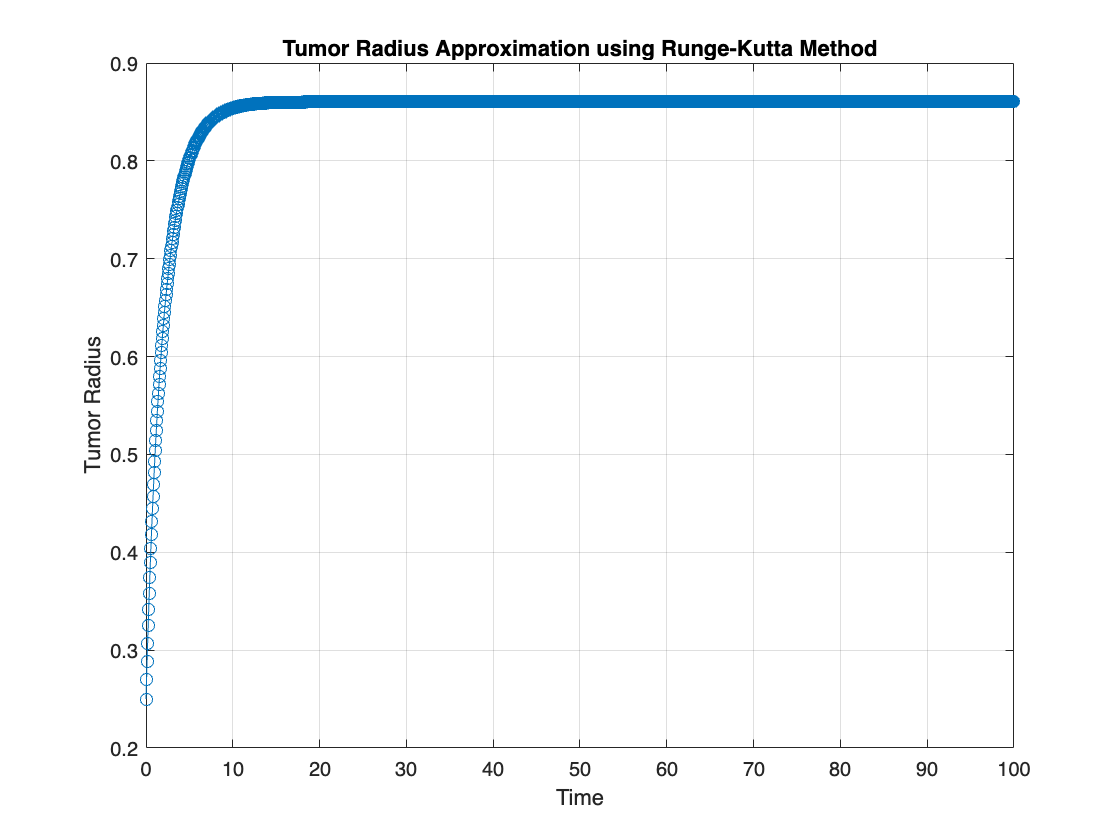

% Plot the solution
plot(t, y, '-o')
title('Tumor Radius Approximation using Runge-Kutta Method');
xlabel('Time');
ylabel('Tumor Radius');
grid on;
hold off

fprintf('The tumor radius aproaches %.4f units as t approaches infinity.', y(end))

The tumor radius aproaches 0.8603 units as t approaches infinity.

## Part 2: Investigate the range of values (up to three decimal places) for the nutrient level $\sigma$ that guarantees the decrease in the tumor radius. Plot the solution curves for $\sigma =\sigma_2$and $\sigma =\sigma_2 +0\ldotp 001$in the same axes to verify that they exhibit different behaviors.

% Initialize parameter values for sigma 1 & 2
sigma1 = 0.021;
sigma2 = 0.022;

%Given function from assignment with sigma1
f1 = @(t, y) -(1/3)*S*y+((2*lambda*sigma1)/(mu*y+sqrt(mu^2*y^2+4*sigma1)));
[t, ysigma1]= RK4(f1, [0,100], 0.25, 1/16)

t =          0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000    1.0625    1.1250    1.1875    1.2500    1.3125    1.3750    1.4375    1.5000    1.5625    1.6250    1.6875    1.7500    1.8125    1.8750    1.9375    2.0000    2.0625    2.1250    2.1875    2.2500    2.3125    2.3750    2.4375    2.5000    2.5625    2.6250    2.6875    2.7500    2.8125    2.8750    2.9375    3.0000    3.0625


ysigma1 =     0.2500    0.2500    0.2500    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2496    0.2495    0.2495    0.2495    0.2495    0.2495    0.2495    0.2495    0.2495


%Given function from assignment sigma2
f2 = @(t, y) -(1/3)*S*y+((2*lambda*sigma2)/(mu*y+sqrt(mu^2*y^2+4*sigma2)));
[t, ysigma2]= RK4(f2, [0,100], 0.25, 1/16)

t =          0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000    1.0625    1.1250    1.1875    1.2500    1.3125    1.3750    1.4375    1.5000    1.5625    1.6250    1.6875    1.7500    1.8125    1.8750    1.9375    2.0000    2.0625    2.1250    2.1875    2.2500    2.3125    2.3750    2.4375    2.5000    2.5625    2.6250    2.6875    2.7500    2.8125    2.8750    2.9375    3.0000    3.0625


ysigma2 =     0.2500    0.2501    0.2503    0.2504    0.2505    0.2507    0.2508    0.2509    0.2510    0.2511    0.2513    0.2514    0.2515    0.2516    0.2517    0.2518    0.2519    0.2520    0.2520    0.2521    0.2522    0.2523    0.2524    0.2524    0.2525    0.2526    0.2527    0.2527    0.2528    0.2529    0.2529    0.2530    0.2531    0.2531    0.2532    0.2532    0.2533    0.2533    0.2534    0.2534    0.2535    0.2535    0.2536    0.2536    0.2537    0.2537    0.2537    0.2538    0.2538    0.2539


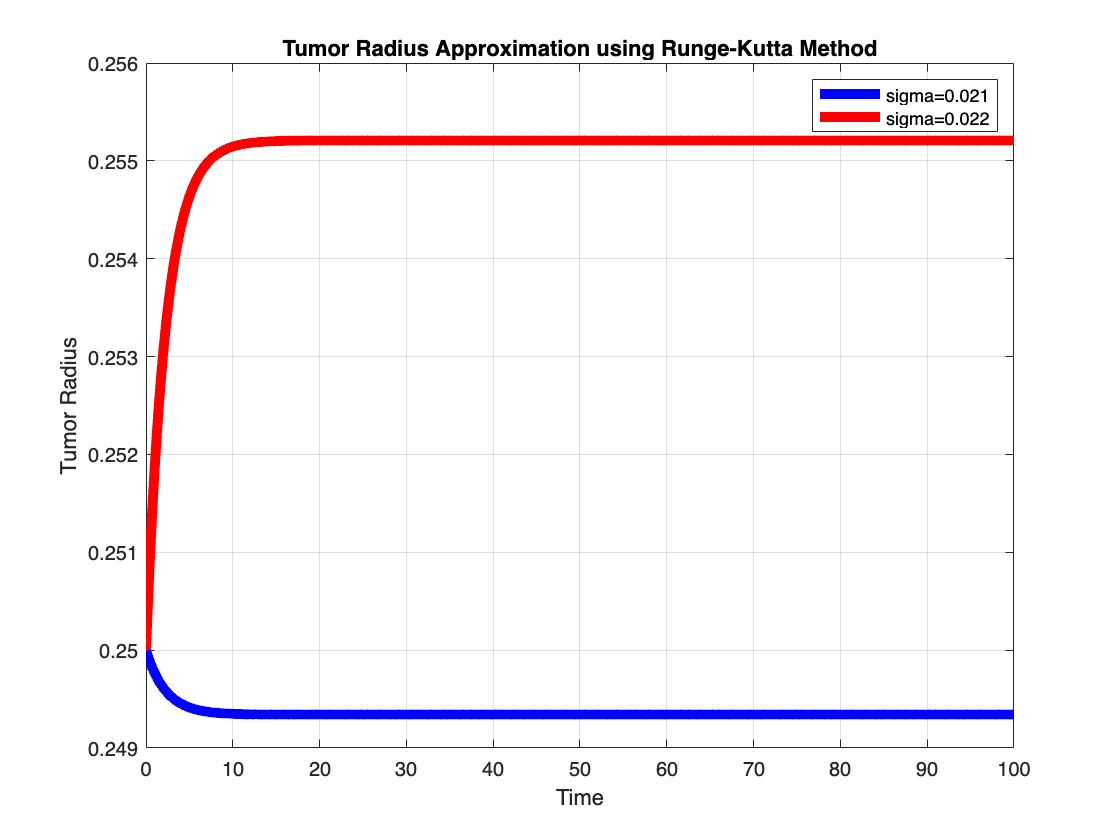

plot(t, ysigma1, '-b', 'LineWidth', 5)
hold on
plot(t, ysigma2, '-r', 'LineWidth', 5)
title('Tumor Radius Approximation using Runge-Kutta Method');
xlabel('Time');
ylabel('Tumor Radius');
legend('sigma=0.021','sigma=0.022');
grid on;

The tumor radius decreases when $0\le \sigma \le 0\ldotp 021$. The tumor radius increases when $\sigma \ge 0\ldotp 022$.

Here is the function used to implement the Runge-Kutta order 4 method:

function [t,y] = RK4(f, tspan, y0, h) % Runge-Kutta order 4 function

    a = tspan(1); % Left side of interval
    b = tspan(end); % Right side of interval
    t = a:h:b; % Step-size of interval

    
    y = zeros(1, length(t));
    y(1)=y0; % Initial value

    for k=1:length(t)-1 % Runge-Kutta equations 
        v1 = f(t(k), y(k));
        v2 = f(t(k)+(h/2), y(k) + 0.5 * h * v1);
        v3 = f(t(k)+(h/2), y(k) + 0.5 * h * v2);
        v4 = f(t(k), y(k) + h * v3);
    
        y(k+1) = y(k) + (h / 6.0) * (v1 +2.0 * (v2 + v3) + v4);

    end
end